# Control Flow Structures - Loop Structures - Part 2

## **What we covered in Part 1**

- Loop structures can be used to automate the process of repeating an instruction.

- There are two kinds of loop structures: For loops and While loops. 

- For loops can be used when the number of iterations is known and While loops can be used when the number of iterations is not known.

- Vecorization can be used to replace loops where each element in an object (i.e array) is treated as a whole object. 

## Introduction

In part 2 we continue learning about fundamental structures in MATLAB and how to use them, particularly we touch on conditional statements and trial structures.

## Conditional Structures

Conditional structures are supported in many programming languages. Conditional structures are used  to specify the use of specific parts in an algorithm that need to be executed. As different conditions are met, different pieces of code are executed. The most common conditional statement is the *if-else-end* statement. We will have a look at various conditional statements in this section. 

### Simple Conditions

The simplest form of a condition structure in pseudo-code is:

where "condition" is an expression. This reads as follows' "If the 'condition' is true, then, the commands in 'statement1' must be executed. 'end' indicates that the condition is complete. If the "condition" is not true then the "statement group" can be bypassed.  Consider a list of names ["Paul", "Sam", "Seth", "Heather", "Sally"] where you only want to print the names that begin with the letter "S". A conditional if statement can be used to check that the first letter of each name contains an "S" and then proceed to print the name.

A simple conditional statement can be extended to check for multiple conditions by using an "elseif" statement. In the generalised pseudo-form this is described as follows,

If condition 1 is satisfied, execute statement  group 1, otherwise  if condition 2 is true then execute statement group 2 and so on and if no statement group is satisfied, the only option is the statement group that is enclosed after the else statement. 

MATLAB Live Editors contain interactive control tasks that you can use to declare variables. An example is a slide bar, using interactive control tasks allows you to  make your Live Editor worksheet robust and it is easier to change variables, update condition values and see the output.

Let's look at an process in code. 

aRandomValue = 44
if aRandomValue > 0
    msgString = sprintf('The Random value is: %d', aRandomValue)
elseif aRandomValue < 0
    msgString = sprintf('The Random value is: %d', aRandomValue)
else 
    msgString = "The random value is zero"
end

Read more about the [sprintf](https://www.mathworks.com/help/matlab/ref/sprintf.html)() built-in function which  formats data into strings or character vectors.

### Conditional Statements and Loop Structures Combined

Oftentimes, conditional and loop structures can be used together to build an algorithm. In the case where each element of an array needs to be processed based on a condition, a loop and a conditional statement can be used.

 In this example, an initial  value "a" is goes through a for loop and accumulates 1 (i.e a + 1) the result is then checked to see if a condition is satisfied  (in this case, if a  is greater than 3). If the condition is satisfied then a display message is returned with the phrase "a is greater than 3". Otherwise the next iteration is performed and the algorithm repeated.  

a = 0;
for counter = 1:5
    a = a + 1;
    if a > 3
        msgString = "a is greater than 3"
    end
end

Now you try! Using a for loop and an if statement and given an array of vegetables, print out all the vegetables that are apples. Write the code in the space below. 

fruits = ["apples", "pears", "pineapples", "apples"];



### Switch-Case Statements

The switch-case statement is similar to multiport switches in real circuits and similar to the use of if-else statements, however there are more suitable for the implementation of discrete conditions. We may compare the pseudo-code statements for both the switch-case and if-else:

As we can see the switch-case statement improves the readability for discrete variables to match. 

In the instance where a radius is specified, we may want to give our programme the ability to choose between the type of area calculation, we could use a switch-case statement to match the desired area calculation. In the example below, based on the selected radius and chosen formula, a switch-case statement is used to calculate the selected area.

radius = 23% meters
calculateType = 'Volume'
switch calculateType
    case 'Perimeter'
        perimeter = 2*pi*radius
    case 'Area'
        area = pi*radius^2
    case 'Volume'
        volume = 4*pi*radius^3/3
end

Now you try! Using a switch-case statement, build an algorithm to calculate the formulae of a specified shape. Consider the 3 shapes: 

- Square Area = $a^2$

- Circle Area = $\pi r^2$

- Rectangle Area = $\textrm{wl}$

Note: ensure that your code has the inputs that are required to calculate the selected area. Write your code in the space below. 

## Trial Structure

When executing a piece of code there may be times when a specific part of your code outputs an unexpected result. This can sometimes cause an error and forcefully stop the execution of your code. In cases where your code takes a bit of time to execute, it will be inconvenient to stop fix and rerun the code. Trials are a special structure in MATLAB which can assist with expected or unexpected outputs in a piece of code. The common structure for a trial structure is specified below;

This structure reads as follows; "The statements in statement group 1 are executed. If an error occurs, an error message is recorded, and the execution is moved to statement group 2. If the execution of statement 1 does not error, then the whole structure is complete and statement group 2 is not executed". Trial structures make a piece of code more reliable and efficient and makes your code less likely to error unexpectedly. 

Consider a non-existent function called "notAFunction()", if there is an error/unexpected result, a default array will be assigned as the output.

try 
    a = notAFunction(5)
catch
    a = [1,2,3]
end

Now you try! Consider an empty function called "emptyFunction" that takes in 2 numerical inputs and has a single output  (i.e **function c = emptyFunction(a,b)**). In a trial statement, deliberately pass in a single input to the function and then use the catch statement to display a warning message. Complete this task in the space below. 

## **Flow Chart**

In summary, the figure below shows the general flow required to complete a set of tasks in an algorithm. This flow chart is used to show the logic of executing each section in an algorithm. The more complex an algorithm gets, the more branches you will see on the flow chart. Flow charts are great for ensuring efficient programming.  

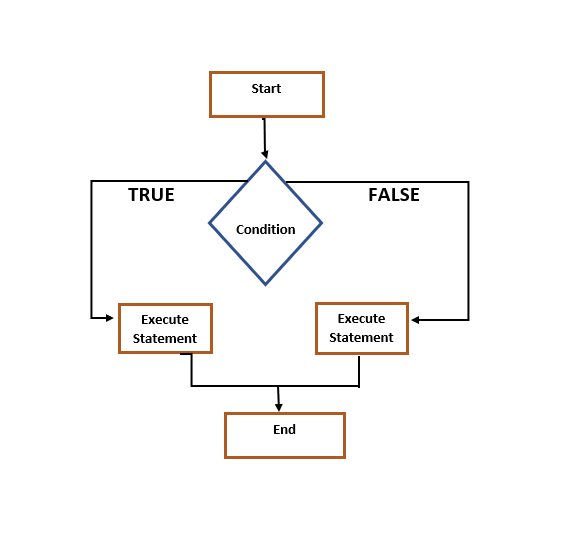

## **What we've covered this week**

This week we learnt about,

- Loop structures can be used to automate the process of repeating an instruction.

- There are two kinds of loop structures: For loops and While loops. 

- For loops can be used when the number of iterations is known and While loops can be used when the number of iterations is not known.

- Vectorization  can be used to replace loops where each element in an object (i.e array) is treated as a whole object. 

- Conditional statements can be used to execute specific parts of an algorithm

## **PowerPoint Presentation**

- [Week_3_Part_2_ControlFlowStructures.pptx](matlab:open('./Week_3_Part_2_ControlFlowStructures.mlx'))

## **Extra **Resources

- [Preallocating Arrays](https://www.mathworks.com/help/matlab/matlab_prog/preallocating-arrays.html)

- [Conditional Statements ](https://www.mathworks.com/help/matlab/matlab_prog/conditional-statements.html)

- [Loop and Conditional Statements](https://www.mathworks.com/help/matlab/control-flow.html?s_tid=CRUX_lftnav)

- [Loop Control Statements ](https://www.mathworks.com/help/matlab/matlab_prog/loop-control-statements.html)

- [Use try catch to Handle Errors](https://www.mathworks.com/help/matlab/matlab_prog/use-trycatch-to-handle-errors.html)

***Copyright 2022 The MathWorks, Inc. & Opti-Num Solutions (Pty) Ltd. ***